%=================================================================
% Signed Graph Metric Learing (SGML) via Gershgorin Disc Alignment
% **example code
%
% author: Cheng Yang
% email me any questions: cheng.yang@ieee.org
% date: June 16th, 2020
% please kindly cite the paper:
% ['Signed Graph Metric Learning via Gershgorin Disc Alignment',
% Cheng Yang, Gene Cheung, Wei Hu,
% https://128.84.21.199/abs/2006.08816]
%=================================================================

clear;clc;close all;

## load sample data (4 out of N samples from 17 binary datasets)

load SGML_data.mat;
% 1. data_feature (number of samples x number of features)
% 2. data_label (number of samples x 1)
disp('1. Australian; 14 features.');

1. Australian; 14 features.


disp('2. Breast-cancer; 10 features.');

2. Breast-cancer; 10 features.


disp('3. Diabetes; 8 features.');

3. Diabetes; 8 features.


disp('4. Fourclass; 2 features.');

4. Fourclass; 2 features.


disp('5. German; 24 features.');

5. German; 24 features.


disp('6. Haberman; 3 features.');

6. Haberman; 3 features.


disp('7. Heart; 13 features.');

7. Heart; 13 features.


disp('8. ILPD; 10 features.');

8. ILPD; 10 features.


disp('9. Liver-disorders; 5 features.');

9. Liver-disorders; 5 features.


disp('10. Monk1; 6 features.');

10. Monk1; 6 features.


disp('11. Pima; 8 features.');

11. Pima; 8 features.


disp('12. Planning; 12 features.');

12. Planning; 12 features.


disp('13. Voting; 16 features.');

13. Voting; 16 features.


disp('14. WDBC; 30 features.');

14. WDBC; 30 features.


disp('15. Sonar; 60 features.');

15. Sonar; 60 features.


disp('16. Madelon; 500 features.');

16. Madelon; 500 features.


disp('17. Colon-cancer; 2000 features.');

17. Colon-cancer; 2000 features.


user_entry = input('please enter number 1-17 (# of the above datasets) to run: ', 's');
data_feature=eval(['data' user_entry '_feature']);
data_label=eval(['data' user_entry '_label']);

[n_sample,n_feature]=size(data_feature); % number of samples, number of features
data_cov=cov(data_feature);

## set parameters

%=main parameters for SGML=================================================
C=n_feature; % constraint of the trace of M
rho=1e-5; % tolerance to make sure M is positive definite during optimization
lobpcg_random_control=0; % random seed for computing the first eigenvector for the first time using LOBPCG
options = optimoptions('linprog','Display','none','Algorithm','interior-point'); % linear program (LP) setting for Frank-Wolfe algorithm
options.OptimalityTolerance = 1e-2; % LP optimality tolerance
options.ConstraintTolerance = 1e-4; % LP interior-point constraint tolerance
FW_dia_offdia_tol=1e-3; % Frank-Wolfe tolerance when optimizing the diagonals + one row/column of off-diagonals
FW_full_tol=1e-5; % Frank-Wolfe tolerance when optimizing the full metric matrix M
max_iter=1e3; % maximum number of iterations for each round of Frank-Wolfe optimization
%==========================================================================

%=parameters for Frank-Wolfe step size optimization========================
GS_or_NR=2; % Frank-Wolfe step size optimization using 1) golden section search or 2) Newton-Raphson method
tol_golden_search=5e-1; % tolerance of golden section search
tol_NR=5e-1; % Newton-Raphson tolerance
tol_GD=5e-1; % gradient descent bisection tolerance
%==========================================================================

%=other parameters=========================================================
gamma = 1; % relative importance of the different-labeled edges to same-labeled edges in the objective function
nv_od=2*n_feature-1; % number of LP variables when optimizing the diagonals + one row/column of off-diagonals
nv_full=n_feature+(n_feature*(n_feature-1))/2; % number of LP variables when optimizing the full metric matrix M
zz=logical(tril(ones(n_feature),-1)); % indices of the lower triangular part of M
dia_idx=(1:n_feature+1:n_feature^2)'; % indices of the diagonals of M
num_list=1:n_feature; % indices of graph nodes of M where the nodes are currently connected
league_vec = ones(n_feature,1); % color set of graph nodes of M
league_vec(2:2:end)=-1; % set it like this so that the odd nodes are blue and even nodes are red
bins=ones(1,n_feature); % the number of the unique numbers of bins represents the number of subgraphs of M
%==========================================================================

%=Initialize M=============================================================
M0=initial_M(n_feature,2); % initial M as a [1-dense matrix] or [2-sparse matrix]

% [M0,league_vec] = determine_initial_M_appropriate_colors(data_cov,...
%     n_feature,...
%     [],...
%     [],...
%     [],...
%     2);

rng(lobpcg_random_control);
[fv1,~] = ...
    lobpcg_fv(randn(n_feature,1),M0,1e-12,200); % compute the first eigenvector for the first time using LOBPCG
scaled_M = (1./fv1) .* M0 .* fv1'; % compute the similarity-transformed M
scaled_factors = (1./fv1) .* ones(n_feature) .* fv1'; % get the scalars of M
%==========================================================================

[LP_A_sparse_i,...
    LP_A_sparse_j,...
    LP_A_sparse_s,...
    LP_b,...
    LP_lb,...
    LP_ub] = LP_setting(n_feature,rho); % get parts of the linear constraints ready for running Matlab linprog

%=run SGML=================================================================
disp('starting SGML.');

starting SGML.


[M]=SGML_main_yasaman(M0,...
    data_feature,...
    data_label,...
    n_sample,...
    n_feature,...
    tol_NR,...
    tol_GD,...
    rho,...
    max_iter,...
    GS_or_NR,...
    tol_golden_search,...
    options,...
    FW_dia_offdia_tol,...
    FW_full_tol,...
    C,...
    gamma,...
    nv_od,...
    nv_full,...
    zz,...
    dia_idx,...
    num_list,...
    league_vec,...
    bins,...
    fv1,...
    scaled_M,...
    scaled_factors,...
    LP_A_sparse_i,...
    LP_A_sparse_j,...
    LP_A_sparse_s,...
    LP_b,...
    LP_lb,...
    LP_ub); % run SGML

initial objective value = 2.176
converged objective value = -14.9089
minimal eigenvalue of M = 1.0004e-05


disp('done with SGML.');

done with SGML.


%==========================================================================

## visualize the initial metric matrix M0

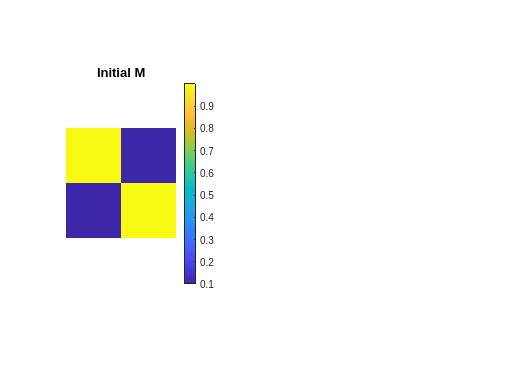

figure(1);subplot(1,2,1);imagesc(M0);title('Initial M');axis off equal;colorbar; % visual check M0

## visualize the SGML learned metric matrix M

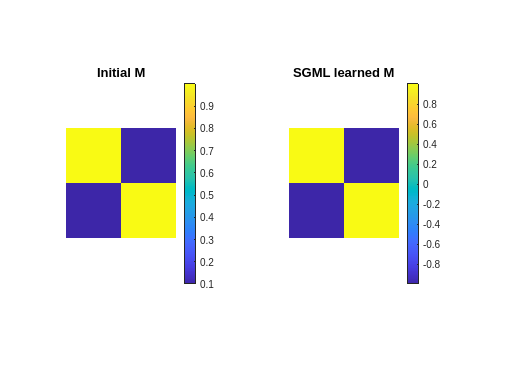

subplot(1,2,2);imagesc(M);title('SGML learned M');axis off equal;colorbar; % visual check M